 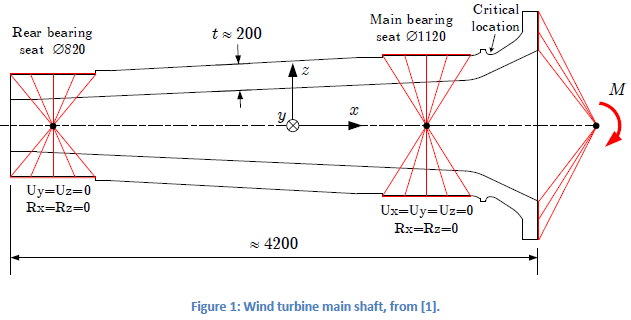

S_a_k = 176.4;
% n = K_t / K_f
E = 169*1e9;
nu = 0.27;
R_m = 400; %MPa 
R_z = 3.2; %m
% P_s = 97.7 procent
y_Mf = 1.265;

alpha_n = 0.32;
beta_n = 0.77;
%point 147431 (a)	204,2	2.521,83374023	-0,00000000	568,65960693
%point 13268 (b)	154,4	2.521,38549805	-0,00000000	563,48132324
x_1 = 568.65960693;
x_2 = 563.48132324;
S_1 = 204.2;
S_2 = 154.4;

S_max = S_a_k

S_max = 176.4000

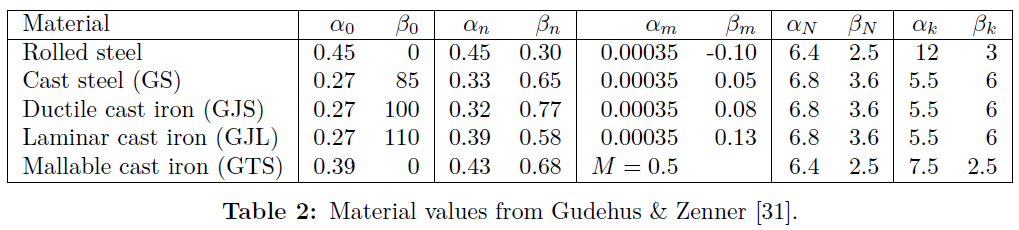


$$\chi^* = \left| \frac{\Delta\sigma}{\sigma_{k,max} \Delta x} \right|$$


X_grad = (S_1/S_max- S_2/S_max)/(x_1 - x_2)

X_grad = 0.0545

n = 1 + alpha_n * X_grad^beta_n

n = 1.0341

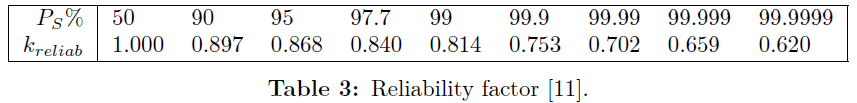

k_chill = 1.5;
k_reliab = 0.840;
k_surf = 1 - 0.22*log10(R_z)^0.64 * log10(R_m) + 0.45*log10(R_z)^0.53

k_surf = 0.9436


t_ref = 25;
t = 147;

alpha_t = 0.15;
k_size = (t_ref/t)^alpha_t

k_size = 0.7666

N_D = 1e6;
N_end = 1e9;
m1 = 5;
m2 = 2*m1 - 1

m2 = 9

alpha_0 = 0.27;
beta_0 = 100;

S_RD_mat = alpha_0 * R_m + beta_0

S_RD_mat = 208


S_RDk = k_size * k_surf * k_reliab * k_chill * n * S_RD_mat / y_Mf

S_RDk = 154.9752

N_S_RDk = C1 / S_RDk^m1 %finder et punkt for S_1 med vores maximale lokal spænding

N_S_RDk = 1.0000e+06



C1 = S_RDk^m1 * N_D

C1 = 8.9395e+16

C2 = S_RDk^m2 * N_D

C2 = 5.1566e+25


N_S_1 = C1 / S_1^m1 %finder et punkt for S_1 med vores maximale lokal spænding

N_S_1 = 2.5179e+05

% Denne spænding ligger på kurven før kneet
N_exp = 2.3e6;
S_exp = (C2 / N_exp)^(1/m2) %finder et punkt for S_1 med vores maximale lokal spænding

S_exp = 141.2766



S_1s = [S_1,S_RDk];
N_1s = [N_S_1,N_D];
S_2s = [S_RDk, S_exp];
N_2s = [N_D, N_exp];

loglog(N_1s, S_1s)
hold on
loglog(N_2s, S_2s)
scatter(N_D,S_RDk, "filled")
xlabel('Number of cycles N')
ylabel('Stress \sigma (MPa)')
ylim([S_exp-10,S_1+10])
xlim([0,N_exp+1e5])
grid("on")

% hold off



S_RDk_no_safe_97 = k_size * k_surf * k_reliab * k_chill * n * S_RD_mat

S_RDk_no_safe_97 = 196.0437

C1_no_safe_97 = S_RDk_no_safe_97^m1 * N_D

C1_no_safe_97 = 2.8958e+17

C2_no_safe_97 = S_RDk_no_safe_97^m2 * N_D

C2_no_safe_97 = 4.2774e+26


N_S_1_no_safe_97 = C1_no_safe_97 / S_1^m1

N_S_1_no_safe_97 = 8.1562e+05

N_D_no_safe_97 = C1_no_safe_97 / S_RDk_no_safe_97^m1 %finder et punkt for S_1 med vores maximale lokal spænding

N_D_no_safe_97 = 1000000

S_exp_no_safe_97 = (C2_no_safe_97 / N_exp)^(1/m2) %finder et punkt for S_1 med vores maximale lokal spænding

S_exp_no_safe_97 = 178.7149


S_1s_no_safe_97 = [S_1,S_RDk_no_safe_97];
N_1s_no_safe_97 = [N_S_1_no_safe_97,N_D];
S_2s_no_safe_97 = [S_RDk_no_safe_97, S_exp_no_safe_97];
N_2s_no_safe_97 = [N_D, N_exp];

loglog(N_1s_no_safe_97, S_1s_no_safe_97, '--')
loglog(N_2s_no_safe_97, S_2s_no_safe_97, '--')



N_RDk_no_safe_97 = C1 / S_RDk_no_safe_97^m1 %finder et punkt for S_1 med vores maximale lokal spænding

N_RDk_no_safe_97 = 3.0871e+05


S_RDk_no_safe_50 = k_size * k_surf * k_chill * n * S_RD_mat

S_RDk_no_safe_50 = 233.3853

N_RDk_no_safe_50 = C1 / S_RDk_no_safe_50^m1 %finder et punkt for S_1 med vores maximale lokal spænding

N_RDk_no_safe_50 = 1.2911e+05

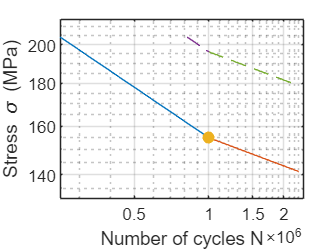


hold off

??